Phys 434 Lab 2 - Abhinav Brahmarouthu

1) 

A&B) Below I will convolve the probability distribution of the background of cosmic rays evolves as more days are added to the sample. As you increase the number of days, this will raise the expected value of cosmic rays proportional to the average times the number of days. This should simply produce a Poission distribution with a lambda equivalent to the expected value of cosmic rays.

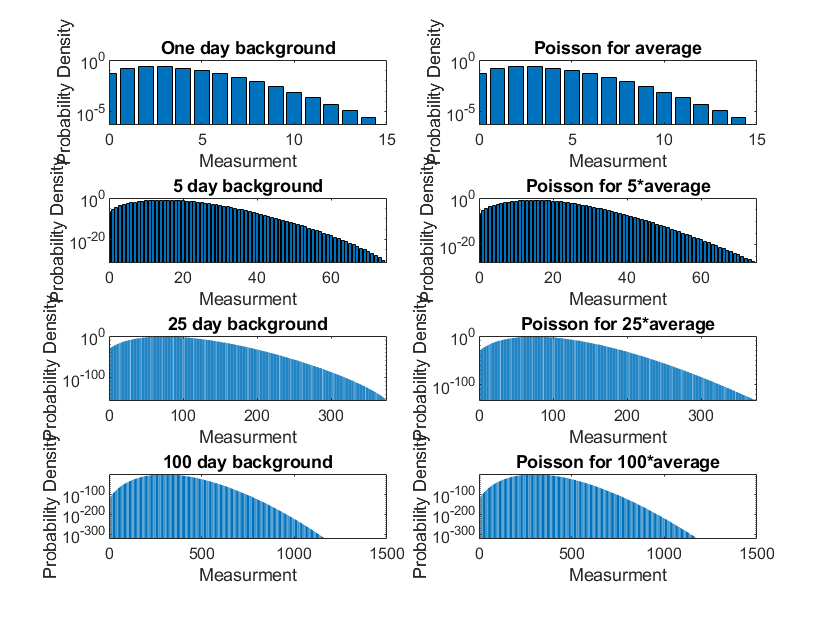

xMin = 0;
xMax = 15;
x = xMin:1:xMax;

avgBackground = 3; %Something between 0.5 and 10
avgSource = 10;    %Larger than background

days = 100;
base = poisspdf(x, avgBackground);  %One day background distribution vector
base = base / sum(base);           %Normalizing
comb = base;
day5 = 0;
day25 = 0;
for i = 1:(days-1)
    comb = conv(comb,base,"full");
    if i == 4
        day5 = comb;
    elseif i == 24
        day25 = comb;    
    end
    
end

subplot(4,2,1)
bar(x, base),set(gca,'yscale','log')
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("One day background")

subplot(4,2,2)
y = poisspdf(x, avgBackground);
bar(x, y),set(gca,'yscale','log')
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Poisson for average")

subplot(4,2,3)
plotMax = (xMax*5);
x = 0:1:plotMax;
bar(x, day5),set(gca,'yscale','log')
xlim([0, plotMax])
xlabel('Measurment')
ylabel('Probability Density')
title("5 day background")

subplot(4,2,4)
y = poisspdf(x, avgBackground*5);
bar(x, y),set(gca,'yscale','log')
xlim([0, plotMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Poisson for 5*average")

subplot(4,2,5)
plotMax = (xMax*25);
x = 0:1:plotMax;
bar(x, day25),set(gca,'yscale','log')
xlim([0, plotMax])
xlabel('Measurment')
ylabel('Probability Density')
title("25 day background")

subplot(4,2,6)
y = poisspdf(x, avgBackground*25);
bar(x, y),set(gca,'yscale','log')
xlim([0, plotMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Poisson for 25*average")

subplot(4,2,7)
plotMax = (xMax*100);
x = 0:1:plotMax;
bar(x, comb),set(gca,'yscale','log')
xlim([0, plotMax])
xlabel('Measurment')
ylabel('Probability Density')
title("100 day background")

subplot(4,2,8)
y = poisspdf(x, avgBackground*100);
bar(x, y),set(gca,'yscale','log')
xlim([0, plotMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Poisson for 100*average")

As seen above, the distribution for one day is a Poisson distribution with a lamda equal to the average number of background of cosmic rays. Then, as more days are summed together, the distribution still matches up perfectley with a Poission distribution with an average equal to the number of days times the average, showing that the distributions remain Possion distributions even for many days. This makes sense that a convolution of Poisson distributions should result in a Poisson distribution, since it would be weird for a distribution to become something else entirely simply by choosing arbitrary time period or x-scale for the distribution. The time period of 1 day, 5 days, and 100 days are all completely arbirarily chosen, and it would be strange for the distribution to change at some arbitrary time scale. 

C)  Now instead of doing a convolution sum, I will compute charts for the average by modifying the x-axis of the plots seen earlier.

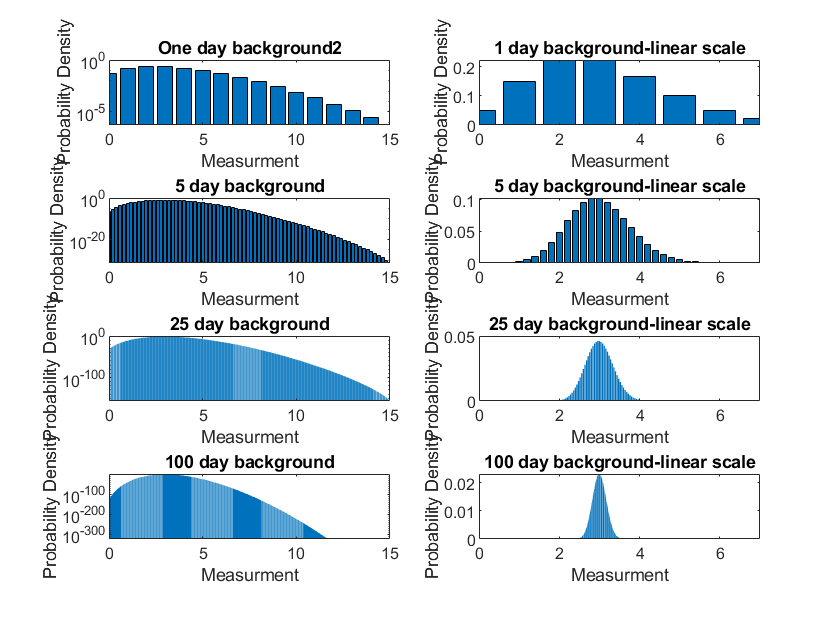

xMin = 0;
xMax = 15;
x = xMin:1:xMax;

figure
subplot(4,2,1)
bar(x, base),set(gca,'yscale','log')
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("One day background2")

subplot(4,2,2)
y = poisspdf(x, avgBackground);
bar(x, y)
xlim([0, 7])
xlabel('Measurment')
ylabel('Probability Density')
title("1 day background-linear scale")

subplot(4,2,3)
xwidth = 1/5;
x = 0:xwidth:xMax;
bar(x, day5),set(gca,'yscale','log')
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("5 day background")

subplot(4,2,4)
bar(x, day5)
xlim([0, 7])
xlabel('Measurment')
ylabel('Probability Density')
title("5 day background-linear scale")

subplot(4,2,5)
xwidth = 1/25;
x = 0:xwidth:xMax;
bar(x, day25),set(gca,'yscale','log')
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("25 day background")

subplot(4,2,6)
bar(x, day25)
xlim([0, 7])
xlabel('Measurment')
ylabel('Probability Density')
title("25 day background-linear scale")

subplot(4,2,7)
xwidth = 1/100;
x = 0:xwidth:xMax;
bar(x, comb),set(gca,'yscale','log')
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("100 day background")

subplot(4,2,8)
bar(x, comb)
xlim([0, 7])
xlabel('Measurment')
ylabel('Probability Density')
title("100 day background-linear scale")

The above plots of the averages starts to look more and more like a gaussian distribution when seen in a linear scale, however maintains its shape as a Poission distribution in the semilog scale as seen on the left hand side of the plots. Notice that the x width becaomes increasingly small in the plots, as with more days, the number of possible averages increases rapidly. While this does not change the shape of the distribution, it does change the number of samples. Thus, when viewed in a linear scale, there is an approximate gaussian distribution at large sample sizes can be explained by the central limit theorem, which states that any distribution approaches a gaussian distribution as the sample size gets large. There is a subtle probability difference when looking at the two sets of plots. In part B, integrating from a point to infinity answers how likely it is to see that number of cosmic rays or greater in one day, at least once in 100 days. The plots from part C instead answer how liekly it is that a given sum of rays over the  entire 100 day period will be a certain quantity.

D) Let's assume that over the course of 25 days, we observed on average, 10 gamma rays per day from a gamma ray source. The probability that this observation, or a more extreeme observation, is the sum of the probabilties from 10 to infnity in the 5 day background average distribution.

xwidth = 1/25;
x = 0:xwidth:xMax;
k = find(x==avgSource); %Find the index where x = the source
digitsOld = digits(100);%Increase rpecision for small numbers
[m, n] = size(day25);    %Find the last index of day25
probability = sum(day25(k:n))   %Sum the relavent probabilities

probability = 1.7871e-57

sigma = abs(norminv(probability))

sigma = 15.9358

This gives a sigma value of over 15, which is much more than needed for a significant result, showing that a signal of only 10, which whould be nowhere near significant if only observed for one day, can become significant if this average is observed over a long period of days.

2. A&B) Now using a continuous Rayleigh distribution instead of the discrete Poisson distribution gives the following resluts:

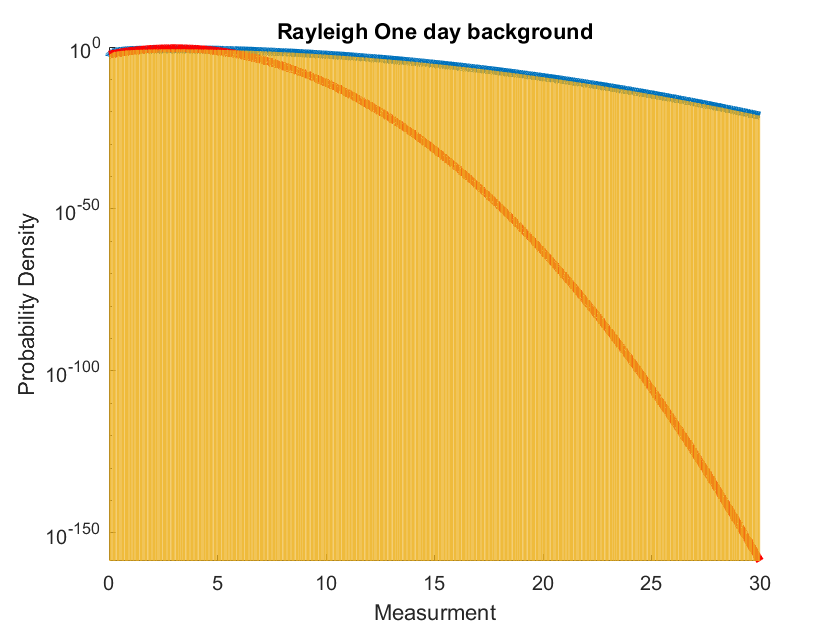

%Copying code from part 1 and modifying to use rayleigh distribution
%instead of poisson
xMin = 0;
xMax = 30;
resolution = 0.01;
x = xMin:resolution:xMax;

avgBackground = 3; %Something between 0.5 and 10
avgSource = 10;    %Larger than background

days = 100;
base = raylpdf(x, avgBackground);  %One day background distribution vector
base = base / sum(base);           %Normalizing
comb = base;
day5 = 0;
day5Center = 0;
day25 = 0;
day25Center = 0;
for i = 1:(days-1)
    comb = conv(comb,base,"full");
    if i == 4
        day5 = comb;
        day5Center = find(day5 == max(day5));
    elseif i == 24
        day25 = comb; 
        day25Center = find(day25 == max(day25));
    end
    
end

%Base Distribution
figure
hold on
y = raylpdf(x, avgBackground);
y2 = normpdf(x, avgBackground);
semilogy(x,y,"LineWidth",4);
semilogy(x,y2,"LineWidth",4, "Color", "Red");
bar(x, base/resolution),set(gca,'yscale','log');
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Rayleigh One day background")
hold off

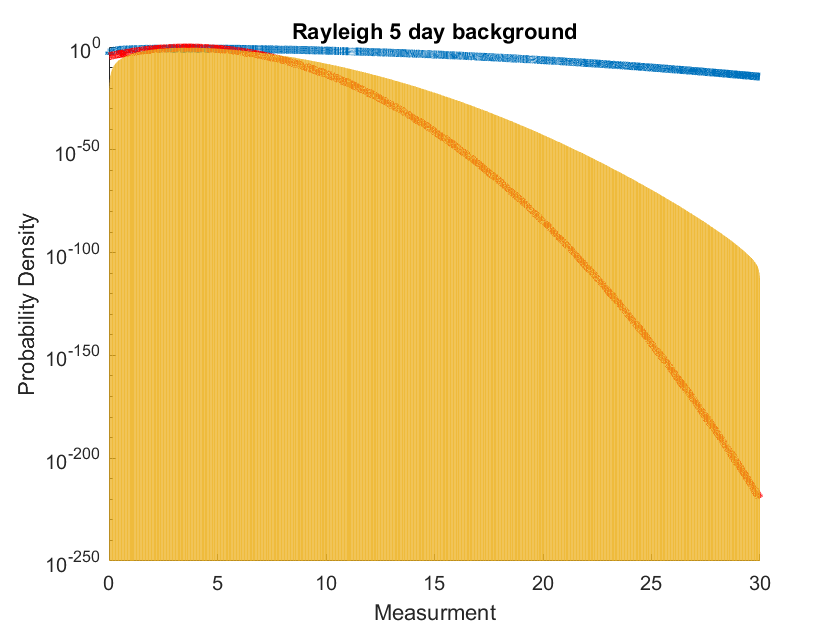


%5 day average
figure
hold on
xwidth = resolution/5;
x = 0:xwidth:xMax;
y = raylpdf(x, x(day5Center));
y2 = normpdf(x, x(day5Center), 0.83);
semilogy(x,y,"LineWidth",4);
semilogy(x,y2,"LineWidth",4, "Color", "Red");
bar(x, day5/xwidth),set(gca,'yscale','log');
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Rayleigh 5 day background")
hold off

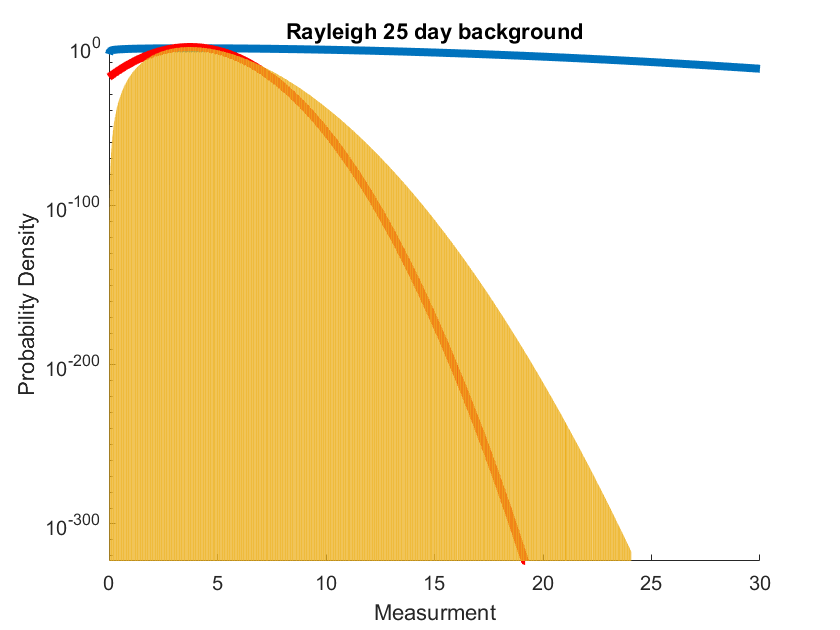


%25 day average
figure
hold on
xwidth = resolution/25;
x = 0:xwidth:xMax;
y = raylpdf(x, x(day25Center));
y2 = normpdf(x, x(day25Center), 0.4);
semilogy(x,y,"LineWidth",4);
semilogy(x,y2,"LineWidth",4, "Color", "Red");
bar(x, day25/xwidth),set(gca,'yscale','log');
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Rayleigh 25 day background")
hold off

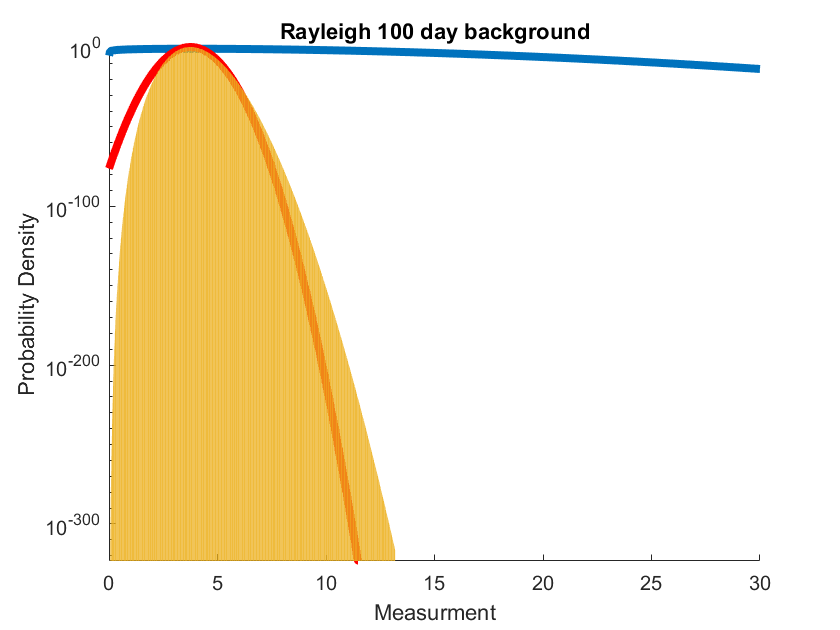


%100 day average
figure
hold on
xwidth = resolution/100;
x = 0:xwidth:xMax;
day100Center = find(comb == max(comb));
y = raylpdf(x, x(day100Center));
y2 = normpdf(x, x(day100Center), 0.2);
semilogy(x,y,"LineWidth",4);
semilogy(x,y2,"LineWidth",4, "Color", "Red");
bar(x, comb/xwidth),set(gca,'yscale','log');
xlim([0, xMax])
xlabel('Measurment')
ylabel('Probability Density')
title("Rayleigh 100 day background")
hold off

As seen in the above plots, as a continuous distribution such as the Rayleigh distribution is averaged repeatedly, it approaches a normal distribution when given enough trials. With the paramaters that I have chosen, the resulting distribution looks to be almost closer to a normal distribution than a rayleigh distribution, and for 25 and 100 days, the rayleigh distribution is an incredibly poor model for the data.

3. A) I will arbitrarily choose a gaussian distribution centered at 5.1, with a sigma of 3.2, and a signal with a value of 25.3.

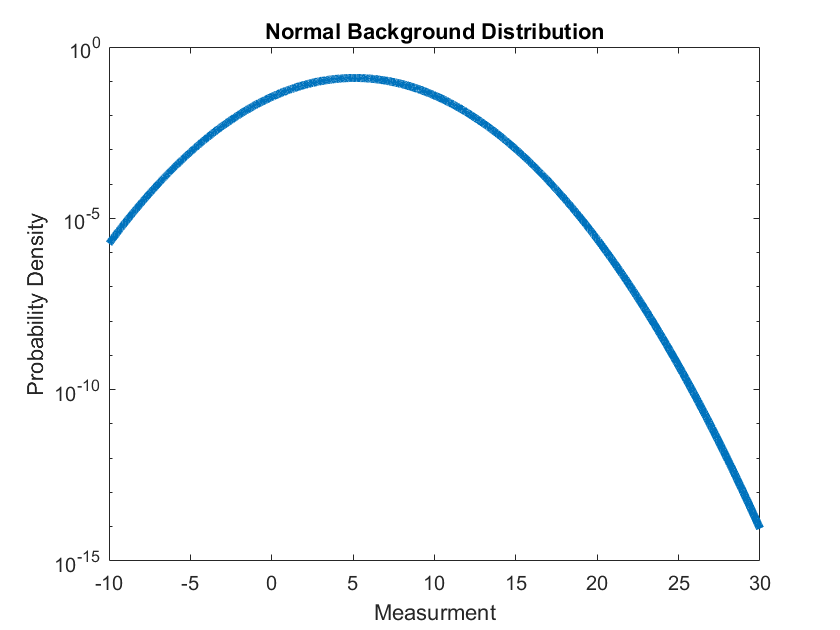

xMin = -10;
xMax = 30;
x = xMin:resolution:xMax;

%create normal distribution
mean = 5.1;
sigma = 3.2;
signal = 25.3;
y = normpdf(x, mean, sigma);
semilogy(x,y,"LineWidth",4);
xlabel('Measurment')
ylabel('Probability Density')
title('Normal Background Distribution')

The probability of finding a measurement of 25 or more extreme is then simply the integral from 25 to infinity:

probability = normcdf(signal, mean, sigma, 'upper')

probability = 1.3728e-10

sigmaSignal = (signal - mean) / sigma

sigmaSignal = 6.3125

This results in a sigma value of 6.31, which is a significant result, and we can claim to have found a real signal that is most likely not caused by background noise.

B&C) If instead I have to look through 10k pixels, now I need to ask the question: what is that chance that the background noise produces at least 25 or larger in at least one of the 10k pixels. Since the chance of a single success in any pixel is small, the chance of a success in multiple pixels simultaneously is increasingly small compared to the chance of a sucess in either due to background noise. Therefore, the chance of a random 25 in one pixel or another can be approximated by the sum of the two probabilities. Therefore the probability of randomly finding a singal in one of the 10k pixels is simply the probability of finding it in one pixel * 10000

probability = 10000*normcdf(signal, mean, sigma, 'upper')

probability = 1.3728e-06

sigmaSignal = abs(norminv(probability))

sigmaSignal = 4.6890

Even though the probability is many orders of magnitude smaller, the sigma is only slightly smaller, at 4.69, which unfortunately is less than 5, resulting in us being unable to claim this as a discovery.

4. A)

%Probability of 5-sigma
fiveSigmaProb = normcdf(5, 'upper');
%Plug into the pdf:
fiveSigmaValueV1 = norminv(1-fiveSigmaProb, mean, sigma)

fiveSigmaValueV1 = 21.1000

Version 1 only requires a signal of strength of about 21.1 to be significant.

B)

fiveSigmaValueV2 = norminv(1-(fiveSigmaProb/10000), mean, sigma)

fiveSigmaValueV2 = 26.0617

Version 2 requires a signal strength of over 26.1 to be considered significant.

C)

penalty = fiveSigmaValueV2 - fiveSigmaValueV1

penalty = 4.9617

The penalty is slightly less than a brighness of about 5 units of a penalty for having 10k trials instead of 1. This penalty is seemingly small for such a large trials increase because we are so far out in the tail of the distribution that even 10k more trials does not cause a large change in the sigma values.

D) Lets try 1 million trials now:

fiveSigmaValueV3 = norminv(1-(fiveSigmaProb/1000000), mean, sigma)

fiveSigmaValueV3 = 28.1614

Increasing the number of trials from 10k to 1 million, two whole orders of magnitude, only increased the neccesary measurement for a 5-sigma result by about 2 units of brightness. This is a seemingly tiny increase in the minimun significant value for 100x as many trials. The sensitivity threshold thus seems small. 